# Pemisah Sampah Organik dan Anorganik Berbasis CNN Yang Dijalankan di Raspberry Pi

## Tahap 1: Import Dataset Yang Dibutuhkan

loc="Dataset";
imds=imageDatastore(loc,'LabelSource',...
    'foldernames','IncludeSubfolders',1,...
    'FileExtensions',{'.png','.jpg','.jfif','.jpeg'});

## Tahap 2 : Inisiasi Ukuran Convolutional Neural Network Dan Augmentasi Gambar

ukuran=[224 224 3];
[train,validate]=splitEachLabel(imds,0.9,'randomize');
train=augmentedImageDatastore(ukuran,train,'ColorPreprocessing','gray2rgb');
validate=augmentedImageDatastore(ukuran,validate,'ColorPreprocessing','gray2rgb');

## Tahap 3 : Pembukaan Aplikasi Deep Network Designer dan Penyajian Hasil Pelatihan CNN Googlenet

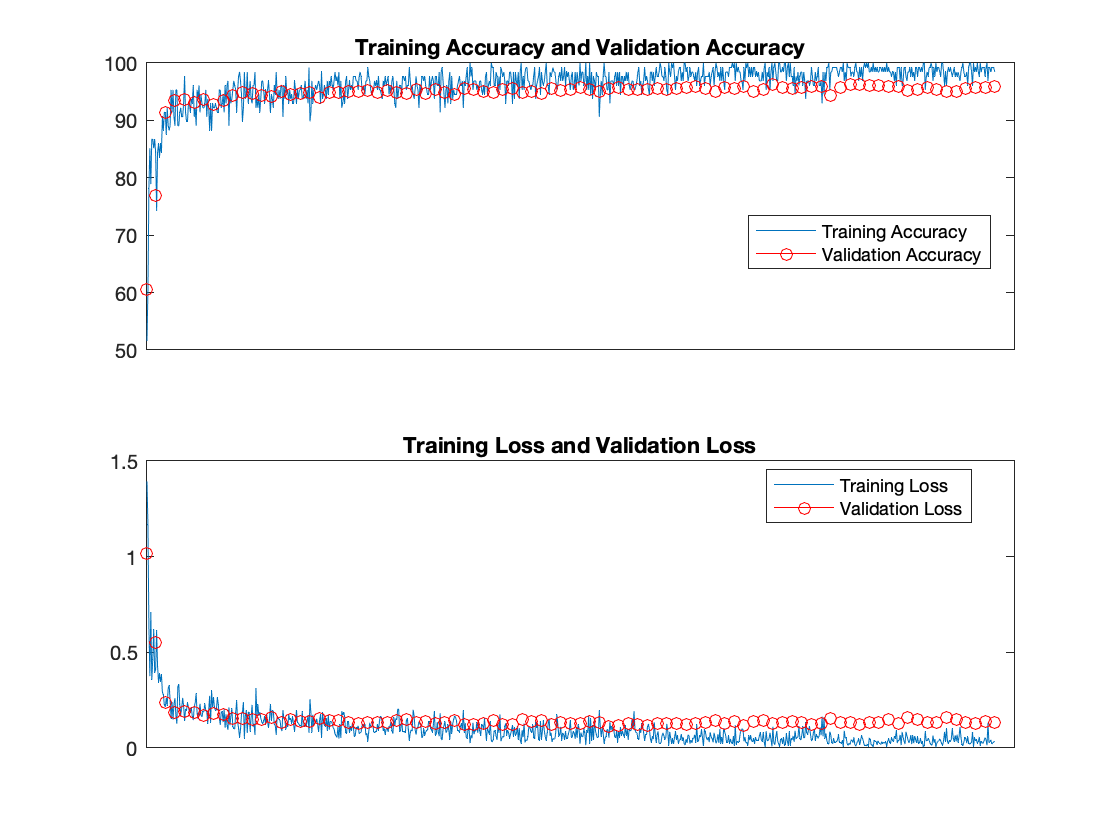

if ~isfolder("Trained_Model")
    deepNetworkDesigner
end
load("Trained_Model/Googlenet_Trained_Network.mat");
load("Trained_Model/Googlenet_Info.mat");

figure(1)
subplot(211)
plot(Googlenet_Info.TrainingAccuracy)
hold on
plot(Googlenet_Info.ValidationAccuracy,'-or')
hold off
legend({'Training Accuracy','Validation Accuracy'},'Location','best')
set(gca,'xtick',[])
title("Training Accuracy and Validation Accuracy")
subplot(212)
plot(Googlenet_Info.TrainingLoss)
hold on
plot(Googlenet_Info.ValidationLoss,'-or')
hold off
legend({'Training Loss','Validation Loss'},'Location','best')
set(gca,'xtick',[])
title("Training Loss and Validation Loss")

## Tahap 4 : Pengujian Model Dengan Gambar Uji Yang Telah Diaugmentasi

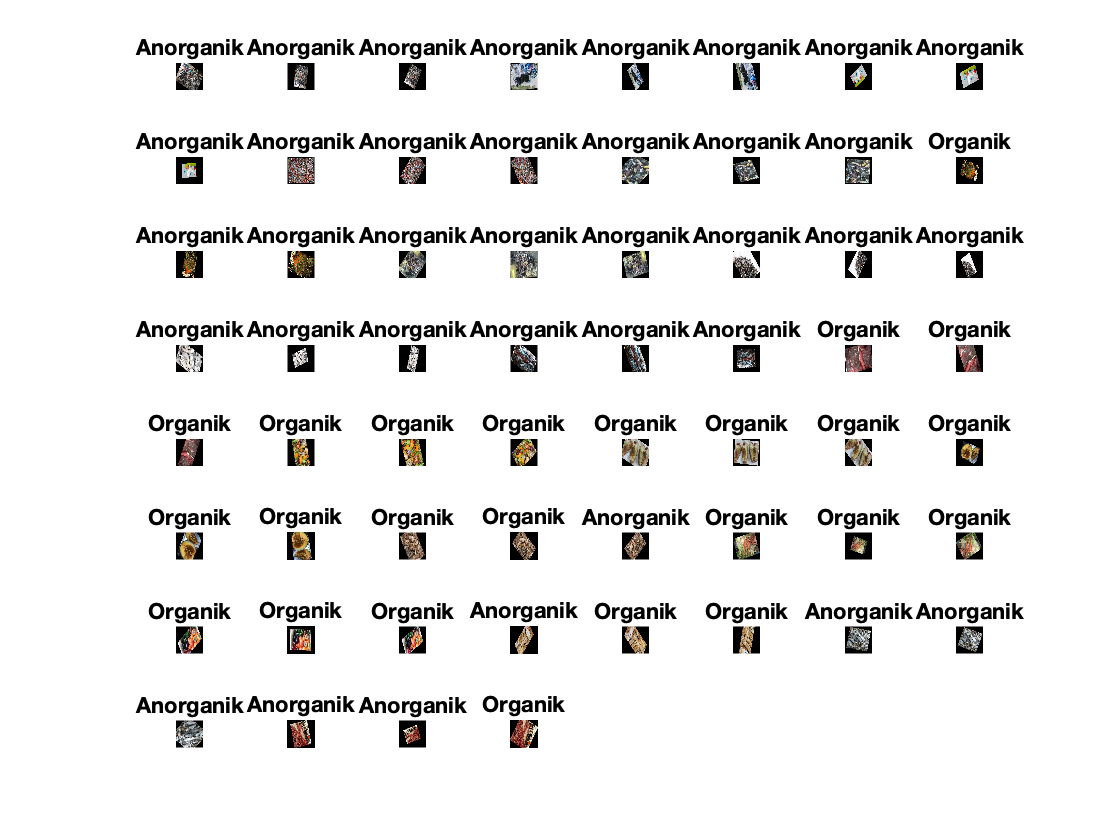

gambar=imageDatastore(fullfile("Gambar Data"),"IncludeSubfolders",true);
j=1;
img={};
c={};
s={};
for i=1:numel(gambar.Files)
    X=gambar.Files(i);
    [p,n,e]=fileparts(X);
    if startsWith(n,'._')
        delete(gambar.Files{i});
    end 
end
while hasdata(gambar)
    img{j}=read(gambar);
    img{j}=imresize(img{j},[224,224]);
    [c{j},s{j}]=classify(Googlenet_Trained_Network,img{j});
    c{j}=cellstr(c{j});
    j=j+1;
end

fig=figure(2);
tlo=tiledlayout(fig,8,8,'TileSpacing','None');

for i=1:numel(img)
    ax=nexttile(tlo);
    imshow(img{i},'Parent',ax);
    title(c{i});
end

## Tahap 5 : Pembuatan Tabel Perbandingan dan Matriks Konvusi

%Anorganik=1;
%Organik=0;
Names={};
Actual={};
ACTUAL=[];
Pred={};
PRED=[];
for i=1:numel(gambar.Files)
    [pp,nn,ee]=fileparts(gambar.Files{i});
    Names{i,1}=nn;
    if startsWith(Names{i,1},'A')
        ACTUAL(i,1)=1;
    end
    if startsWith(Names{i,1},'O')
        ACTUAL(i,1)=0;
    end
    [Pred{i,1},~]=classify(Googlenet_Trained_Network,imresize(img{i},[224,224]));
    Pred{i,1}=string(Pred(i,1));
    if strcmp(Pred{i,1},"Anorganik")
        PRED(i,1)=1;
    end
    if strcmp(Pred{i,1},"Organik")
        PRED(i,1)=0;
    end
end
T=table(Names,ACTUAL,PRED);
SC=ACTUAL==PRED;
Res=sum(SC)/(numel(SC));
sprintf("Performa Model Untuk Membedakan Gambar Adalah : %f Persen",Res)

ans = "Performa Model Untuk Membedakan Gambar Adalah : 0.866667 Persen"

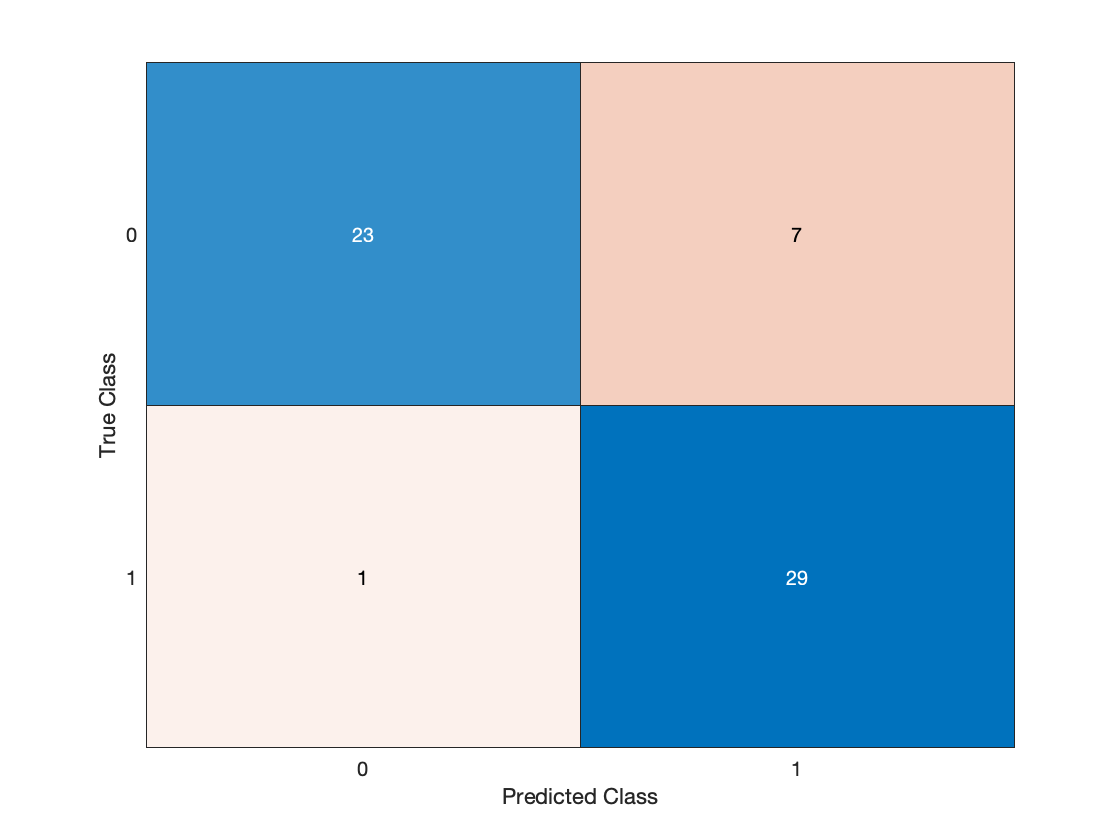

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


figure(3)
cm=confusionchart(ACTUAL,PRED)

## Tahap 6 : Modifikasi Program Agar Bisa Memilih Gambar Bebas

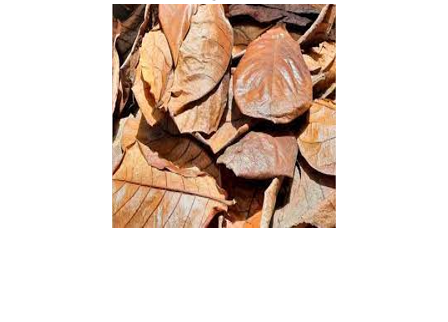

[gambar_bebas,te]=uigetfile('*','Silahkan Pilih Gambar Sampah Yang Diinginkan');
ranI=fullfile(te,gambar_bebas);
ranI=imread(ranI);
ranI=imresize(ranI,[224,224]);
[PR,~]=classify(Googlenet_Trained_Network,ranI);

figure(4)
imshow(ranI)
title(string(PR))

cd Trained_Model

board=targetHardware("Raspberry Pi");
board.CoderConfig.TargetLang="C++";
 
dlcfg=coder.DeepLearningConfig("arm-compute");
dlcfg.ArmArchitecture="armv7";
dlcfg.ArmComputeVersion="19.05"; 
board.CoderConfig.DeepLearningConfig=dlcfg;

deploy(board,'raspi_googlenet_trash_class');

Error connecting to SSH server at 192.168.1.174
Use help codegen for more information on using this command.
